data=readtable("elevator_test_4_21_2.csv")

data = 1500×15 table
    TimeSinceLaunch_ms_    XAcceleration_m_s_    YAcceleration_m_s_    ZAcceleration_m_s_    XOrientation    YOrientation    ZOrientation    GlobalZAccel    Altitude_m_    Latitude    Longitude      Phase       KalmanAltitude    GlobalZVel    KalmanGlobalZAccel
    ___________________    __________________    __________________    __________________    ____________    ____________    ____________    ____________    ___________    ________    _________    __________    ______________    ____

% break_points = [];
% for i=2:length(data.TimeSinceLaunch_ms_)
%     if data.TimeSinceLaunch_ms_(i) < data.TimeSinceLaunch_ms_(i-1)
%         break_points(end+1) = i;
%     end
% end

break_points

break_points = 56

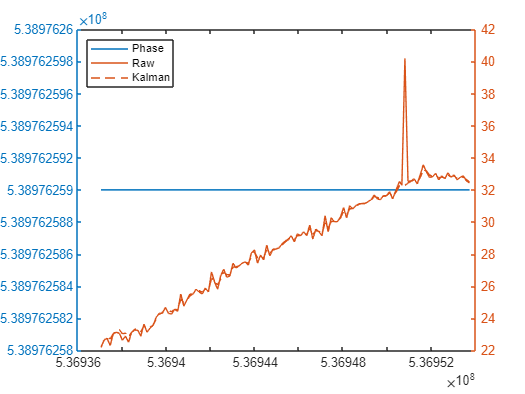

clf

windows_start = 1;
windowd_end = 121;

yyaxis left
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.Phase(windows_start:windowd_end))

yyaxis right

plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.Altitude_m_(windows_start:windowd_end))
hold on
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.KalmanAltitude(windows_start:windowd_end))
legend("Phase", "Raw", "Kalman", "Location", "northwest")

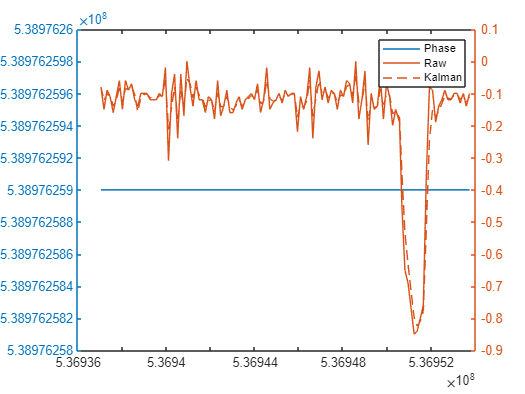

clf


yyaxis left
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.Phase(windows_start:windowd_end))

yyaxis right
hold on
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.GlobalZAccel(windows_start:windowd_end))
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.KalmanGlobalZAccel(windows_start:windowd_end))
%plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.GlobalZVel(windows_start:windowd_end))

legend("Phase", "Raw", "Kalman")

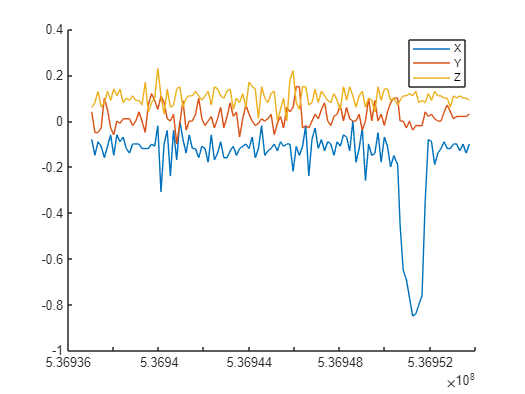

clf


hold on
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.XAcceleration_m_s_(windows_start:windowd_end))
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.YAcceleration_m_s_(windows_start:windowd_end))
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.ZAcceleration_m_s_(windows_start:windowd_end))
legend("X", "Y", "Z")

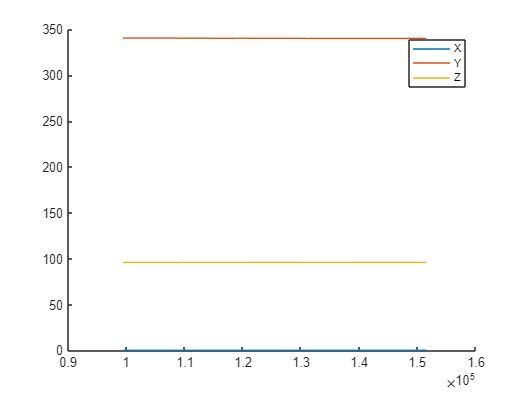

clf


hold on
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.XOrientation(windows_start:windowd_end))
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.YOrientation(windows_start:windowd_end))
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), data.ZOrientation(windows_start:windowd_end))
legend("X", "Y", "Z")

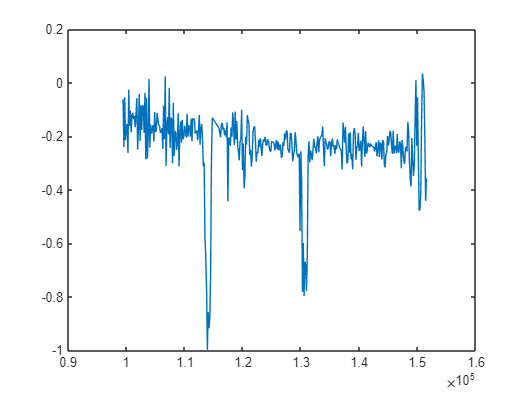

alpha = mean(data.XOrientation(windows_start:windowd_end)) * pi / 180;
beta = mean(data.YOrientation(windows_start:windowd_end)) * pi / 180;

x_comp = -1*sin(beta) * data.XAcceleration_m_s_(windows_start:windowd_end);
y_comp = cos(beta) * sin(alpha) * data.YAcceleration_m_s_(windows_start:windowd_end);
z_comp = cos(alpha) * cos(beta) * data.ZAcceleration_m_s_(windows_start:windowd_end);

z_global = x_comp + y_comp+ z_comp;
clf
plot(data.TimeSinceLaunch_ms_(windows_start:windowd_end), z_global)